clear all

## Loading memories

Let us load `memories` and `memoryNames` from disk.

load('Matlab/input/imagePaterns.mat')

Let us also define the number of memories and the number of neurons for later use.

[m,n] = size(memories);

## Considering the relation between the memories

We will look at the distance of each memory to each other memory. This will give us a rough indication about how close the memories are to each other.

distMemories = zeros(m,m);
for i = 1:m
    for j = 1:m
        distMemories(i,j) = hamdist(memories(i,:),memories(j,:));
    end
end

distMemories

distMemories =      0    20    26    29
    20     0    28    31
    26    28     0    29
    29    31    29     0


## Training our models

Let us train a model for each of our learning rules based on these memories.

hebiNet = HopfieldNet(n, 'Hebbian');
hebiNet = hebiNet.train(memories);

storNet = HopfieldNet(n, 'Storkey');
storNet = storNet.train(memories);

projNet = HopfieldNet(n, 'Projection');
projNet = projNet.train(memories);

## Running the simulations

We will run the simulation for 1000 iterations per distortion level. We will do this for all possible distortion levels (0 to n in our case).

hebiOutput = robustnessFunc(hebiNet, 1000, 0:n);
storOutput = robustnessFunc(storNet, 1000, 0:n);
projOutput = robustnessFunc(projNet, 1000, 0:n);

## Determining the rubustness of each learning rule

We will start by plotting the data obtained from running the simulations. Since we are considering 4 memories in our example, we will plot the results using a subplot of size 2 by 2.

gridRow = 2; 
gridCol = 2;

### Hebbian

figure('Name','Hebbian')
fprintf("Learning rule: %s\n",'Hebbian')

Learning rule: Hebbian


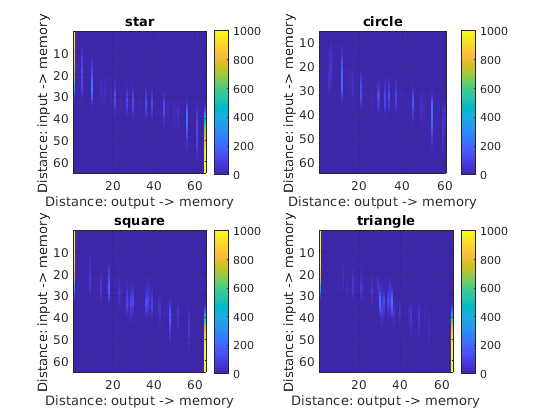

for i = 1:m
    subplot(gridRow,gridCol,i);
    image(hebiOutput(:,:,i),'CDataMapping','scaled');
    title(memoryNames(i))
    xlabel('Distance: output -> memory')
    ylabel('Distance: input -> memory')
    colorbar
    grid on
end

### Storkey

figure('Name','Storkey')
fprintf("Learning rule: %s\n",'Storkey')

Learning rule: Storkey


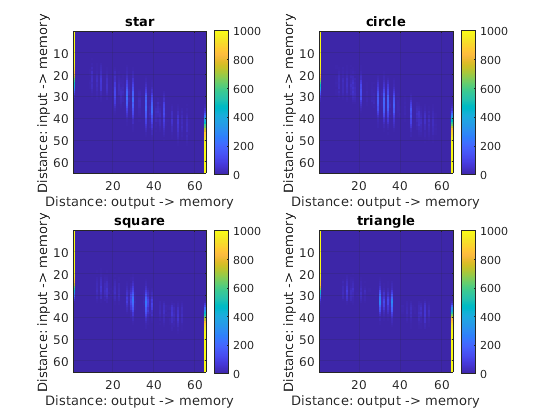

for i = 1:m
    subplot(gridRow,gridCol,i);
    image(storOutput(:,:,i),'CDataMapping','scaled');
    title(memoryNames(i))
    xlabel('Distance: output -> memory')
    ylabel('Distance: input -> memory')
    colorbar
    grid on
end

#### Projection / Pseudo inverse

figure('Name','Pseudo-Inverse')
fprintf("Learning rule: %s\n",'Pseudo-Inverse')

Learning rule: Pseudo-Inverse


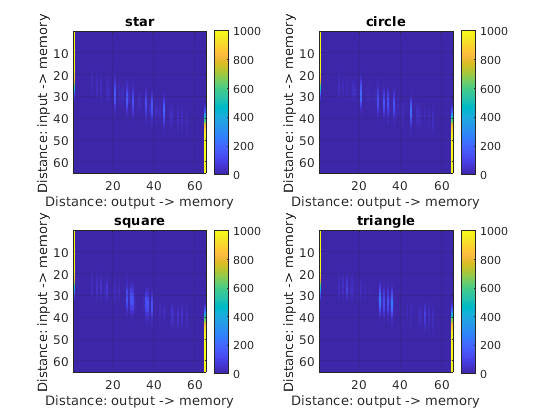

for i = 1:m
    subplot(gridRow,gridCol,i);
    image(projOutput(:,:,i),'CDataMapping','scaled');
    title(memoryNames(i))
    xlabel('Distance: output -> memory')
    ylabel('Distance: input -> memory')
    colorbar
    grid on
end

## Determining the accuracy per distortion level

We will start by combining the data of each memory into 1 matrix.

hebiSumOutput = zeros(n+1,n+1);
storSumOutput = zeros(n+1,n+1);
projSumOutput = zeros(n+1,n+1);
for mem_idx = 1:m
    hebiSumOutput = hebiOutput(:,:,mem_idx);
    storSumOutput = storOutput(:,:,mem_idx);
    projSumOutput = projOutput(:,:,mem_idx);
end

We will normalise this data such that it will be between 0 and 1.

for idx = 1:n+1
    hebiSumOutput(idx,:) = hebiSumOutput(idx,:) / sum(hebiSumOutput(idx,:));
    storSumOutput(idx,:) = storSumOutput(idx,:) / sum(storSumOutput(idx,:));
    projSumOutput(idx,:) = projSumOutput(idx,:) / sum(projSumOutput(idx,:));
end

Now that we have prepared our data we can plot it.

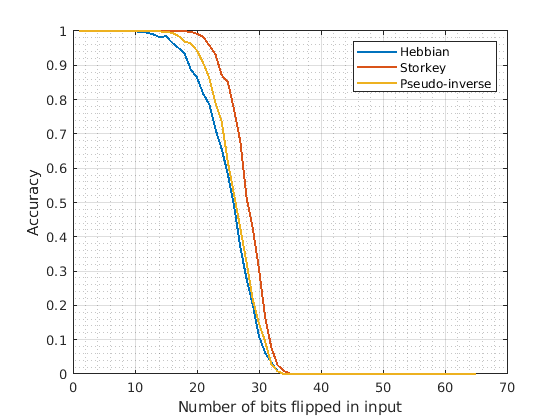

figure('Name','Accuracy')
plot(1:n+1,hebiSumOutput(:,1),'LineWidth',1.5)
hold on
plot(1:n+1,storSumOutput(:,1),'LineWidth',1.5)
plot(1:n+1,projSumOutput(:,1),'LineWidth',1.5)
hold off
xlabel('Number of bits flipped in input')
ylabel('Accuracy')
legend('Hebbian', 'Storkey', 'Pseudo-inverse')
grid on
grid minor